## Part 2: Varying parameters

- Calculate the thrust and SFC for each variation

- Plot the variation of thrust and SFC vs. FPR, BPR, OPR, TIT

Characteristics:

clear all
close all
clc

pi_inlet = 0.98; %Inlet Pressure Ratio
m = 173;%Engine Air Mass flow rate [kg/s]
BPR = 12; %Bypass Ratio
FPR = 1.4; %Fan Pressure Ratio
pi_LPC = 1.7; %LPC Pressure Ratio
pi_HPC = 12.5; %HPC Pressure Ratio
TIT = 1400; %Turbine Inlet Temperature [K]
eta_fan = 0.9; %Fan isentropic efficiency
eta_comp = 0.92; %LPC & HPC isentropic efficiency
eta_turb = 0.9; %LPT & HPT isentropic efficiency
eta_mec = 0.99; %Mechanical efficiency
eta_comb = 0.995; %Combustor efficiency
pi_comb = 0.96; %Combustor pressure ratio
eta_noz = 0.98; %Nozzle efficiency
M = 0.78; %Mach number
h = 10668; %Altitude [m]
T_amb = 218.8; %Ambient Temperature [K]
P_amb = 23842; %Ambient Pressure [Pa]
R = 287; %Gas constant [J/(Kg*K)]
LHV = 43000000; %Fuel Calorific Value [J/Kg]
cp_a = 1000; %Specific heat at constant pressure for air [J/(Kg*K)]
g_a = 1.4; %Specific heat ratio for air
cp_gas = 1150; %Specific heat at constant pressure for combusted gases [J/(Kg*K)]
g_gas = 1.33; %Specific heat ratio for combusted gases

## Varying the bypass ratio from [9,11,13] with FPR of 1.4 and 1.5 respectively

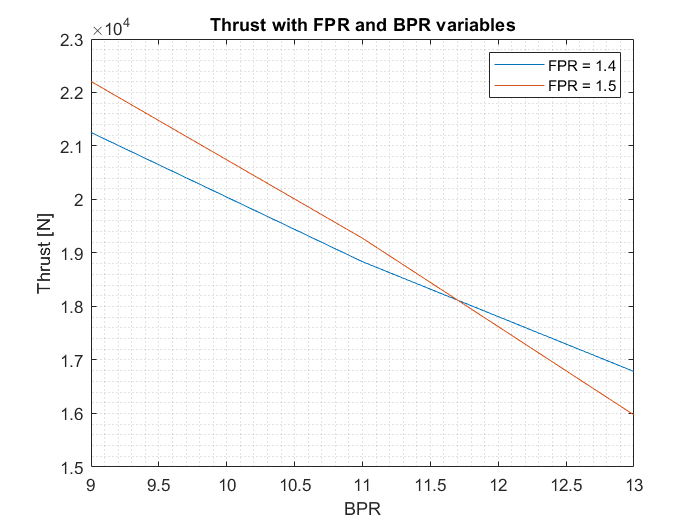

VFPR = [1.4, 1.5];
VBPR = [9,11,13];

for i = 1:size(VFPR,2)
    for j = 1:size(VBPR,2)

        FPR = VFPR(i);
        BPR = VBPR(j);

        v_0 = M*sqrt(g_a*R*T_amb);
        T_ta = T_amb*(1+ ((g_a-1)/2)*M^2);
        T_t2 = T_ta;
        P_ta = P_amb*(1+ ((g_a-1)/2)*M^2)^(g_a/(g_a-1));
        P_t2 = P_ta*pi_inlet;
        %Fan
        P_t21 = P_t2*FPR;
        P_t13 = P_t21;
        T_t21 = T_t2*(1 + (1/eta_fan)*(FPR^((g_a-1)/g_a) -1));
        T_t13 = T_t21;
        W_fan = m*cp_a*(T_t21-T_t2);
        m_hot = m/(BPR+1);
        m_cold = m_hot*BPR;
        W_fan_hot = m_hot*cp_a*(T_t21-T_t2);
        W_fan_cold = m_cold*cp_a*(T_t21-T_t2);
        %Compressors
        P_t25 = P_t21*pi_LPC;
        P_t3 = P_t25*pi_HPC;
        T_t25 = T_t21*(1 + (1/eta_comp)*(pi_LPC^((g_a-1)/g_a) -1));
        T_t3 = T_t25*(1 + (1/eta_comp)*(pi_HPC^((g_a-1)/g_a) -1));
        W_LPC = m_hot*cp_a*(T_t25-T_t21);
        W_HPC = m_hot*cp_a*(T_t3-T_t25);
        %Combustion chamber
        m_f = (m_hot*(cp_gas*TIT-cp_a*T_t3))/(eta_comb*LHV);
        m_gas = m_hot + m_f;
        P_t4 = P_t3*pi_comb;
        %HPT:
        W_HPT = W_HPC/eta_mec;
        T_t45 = TIT-W_HPT/(m_gas*cp_gas);
        P_t45 = P_t4*(1- (1/eta_turb)*(1- T_t45/TIT))^(g_gas/(g_gas-1));
        %LPT:
        W_LPT = (W_LPC+W_fan)/eta_mec;
        W_45g = (W_LPC+W_fan_hot)/eta_mec;
        T_tg = T_t45- W_45g/(m_gas*cp_gas);
        T_t5 = T_t45- W_LPT/(m_gas*cp_gas);
        P_t5 = P_t45*(1- (1/eta_turb)*(1- T_t5/T_t45))^(g_gas/(g_gas-1));
        P_tg = P_t45*(1- (1/eta_turb)*(1- T_tg/T_t45))^(g_gas/(g_gas-1));
        P_8is = P_amb;
        T_8is = T_tg*(P_8is/P_tg)^((g_gas-1)/g_gas);
        W_gg = m_gas*cp_gas*(T_tg-T_8is);
        %Core Nozzle:
        T_t7 = T_t5;
        T_t8 = T_t7;
        P_t7 = P_t5;
        Crit_ratio = (1- (1/eta_noz)*((g_gas-1)/(g_gas+1)))^(-g_gas/(g_gas-1));
        if P_t7/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
            M_8 = 1;
            T_8 = T_t7*(2/(g_gas+1));
            P_8 = P_t7/(Crit_ratio);
            v_8 = sqrt(g_gas*R*T_8);
            r_8 = P_8/(R*T_8);
            A_8 = m_gas/(r_8*v_8);
        else %unchocked nozzle
            P_8 = P_amb;
            T_8 = T_t8*(1 -eta_noz*(1- (P_8/P_t7)^((g_gas-1)/g_gas)));
            M_8 = sqrt((T_t8/T_8 -1)*(2/(g_gas-1)));
            v_8 = M_8*sqrt(g_gas*R*T_8);
            r_8 = P_8/(R*T_8);
            A_8 = m_gas/(r_8*v_8);
        end
        P_t8 = P_8*(1 + ((g_gas-1)/2)*M_8^2)^(g_gas/(g_gas-1));
        %Bypass Nozzle:
        T_t16 = T_t13;
        P_t16 = P_t13;
        Crit_ratio = (1- (1/eta_noz)*((g_a-1)/(g_a+1)))^(-g_a/(g_a-1));
        if P_t16/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
            M_18 = 1;
            T_18 = T_t16*(2/(g_a+1));
            P_18 = P_t16/(Crit_ratio);
            v_18 = sqrt(g_a*R*T_18);
            r_18 = P_18/(R*T_18);
            A_18 = m_cold/(r_18*v_18);
        else %unchocked nozzle
            P_18 = P_amb;
            T_18 = T_t18*(1 -eta_noz*(1- (P_18/P_t16)^((g_a-1)/g_a)));
            M_18 = sqrt((T_t18/T_18 -1)*(2/(g_a-1)));
            v_18 = M_18*sqrt(g_a*R*T_18);
            r_18 = P_18/(R*T_18);
            A_18 = m_cold/(r_18*v_18);
        end
        P_t18 = P_18*(1 + ((g_a-1)/2)*M_18^2)^(g_a/(g_a-1));
        %Performance parameters:
        F_core = m_gas*v_8 - m_hot*v_0 + A_8*(P_8-P_amb);
        v_8eff = (m_hot*v_0+F_core)/m_gas;
        F_bp = m_cold*(v_18-v_0) + A_18*(P_18-P_amb);
        v_18eff = v_0+F_bp/m_cold;
        F(i,j) = F_core+F_bp;
        TSFC(i,j) = m_f/F(i,j);
    end
end
figure("Name","Thrust with FPR and BPR variables")
plot(VBPR,F(1,:))
hold on
plot(VBPR,F(2,:))
xlabel("BPR")
ylabel("Thrust [N]")
legend(["FPR = 1.4", "FPR = 1.5"])
title("Thrust with FPR and BPR variables")
grid("minor")

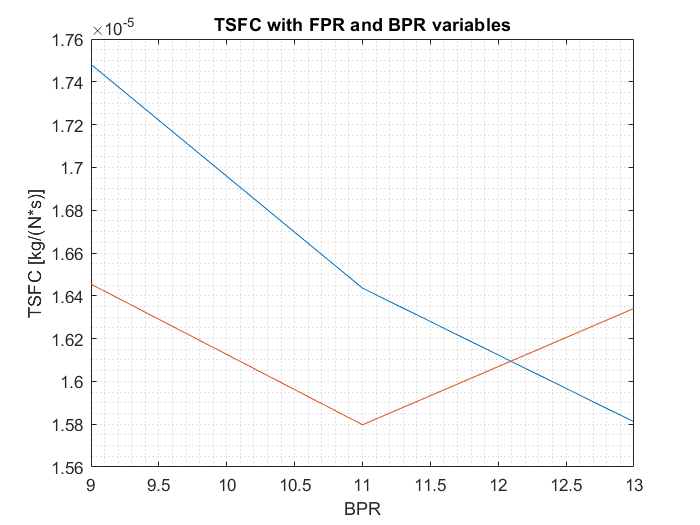

figure("Name","TSFC with FPR and BPR variables")
plot(VBPR,TSFC(1,:))
hold on
plot(VBPR,TSFC(2,:))
xlabel("BPR")
ylabel("TSFC [kg/(N*s)]")
title("TSFC with FPR and BPR variables")
grid("minor")


%once I have finished to upload the values of FPR and BPR, I put the
%original values for the next variations

BPR = 12; %Bypass Ratio
FPR = 1.4; %Fan Pressure Ratio

%given that the next time I am going to use F and TSFC as vectors and not
%matrixes, I am going to change their size, so it is better to delete them
%as variables
clear F
clear TSFC

## Varying the HPC pressure ratio from [11, 13, 15]

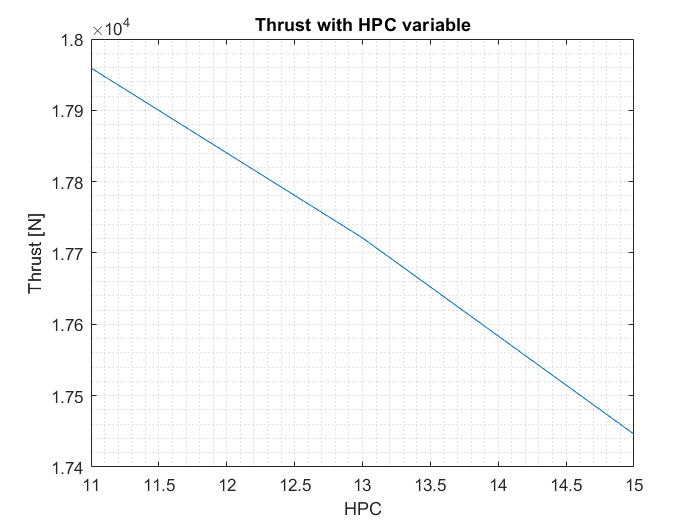

VHPC = [11, 13, 15];
for i = 1:size(VHPC,2)
    pi_HPC = VHPC(i);

    v_0 = M*sqrt(g_a*R*T_amb);
    T_ta = T_amb*(1+ ((g_a-1)/2)*M^2);
    T_t2 = T_ta;
    P_ta = P_amb*(1+ ((g_a-1)/2)*M^2)^(g_a/(g_a-1));
    P_t2 = P_ta*pi_inlet;
    %Fan
    P_t21 = P_t2*FPR;
    P_t13 = P_t21;
    T_t21 = T_t2*(1 + (1/eta_fan)*(FPR^((g_a-1)/g_a) -1));
    T_t13 = T_t21;
    W_fan = m*cp_a*(T_t21-T_t2);
    m_hot = m/(BPR+1);
    m_cold = m_hot*BPR;
    W_fan_hot = m_hot*cp_a*(T_t21-T_t2);
    W_fan_cold = m_cold*cp_a*(T_t21-T_t2);
    %Compressors
    P_t25 = P_t21*pi_LPC;
    P_t3 = P_t25*pi_HPC;
    T_t25 = T_t21*(1 + (1/eta_comp)*(pi_LPC^((g_a-1)/g_a) -1));
    T_t3 = T_t25*(1 + (1/eta_comp)*(pi_HPC^((g_a-1)/g_a) -1));
    W_LPC = m_hot*cp_a*(T_t25-T_t21);
    W_HPC = m_hot*cp_a*(T_t3-T_t25);
    %Combustion chamber
    m_f = (m_hot*(cp_gas*TIT-cp_a*T_t3))/(eta_comb*LHV);
    m_gas = m_hot + m_f;
    P_t4 = P_t3*pi_comb;
    %HPT:
    W_HPT = W_HPC/eta_mec;
    T_t45 = TIT-W_HPT/(m_gas*cp_gas);
    P_t45 = P_t4*(1- (1/eta_turb)*(1- T_t45/TIT))^(g_gas/(g_gas-1));
    %LPT:
    W_LPT = (W_LPC+W_fan)/eta_mec;
    W_45g = (W_LPC+W_fan_hot)/eta_mec;
    T_tg = T_t45- W_45g/(m_gas*cp_gas);
    T_t5 = T_t45- W_LPT/(m_gas*cp_gas);
    P_t5 = P_t45*(1- (1/eta_turb)*(1- T_t5/T_t45))^(g_gas/(g_gas-1));
    P_tg = P_t45*(1- (1/eta_turb)*(1- T_tg/T_t45))^(g_gas/(g_gas-1));
    P_8is = P_amb;
    T_8is = T_tg*(P_8is/P_tg)^((g_gas-1)/g_gas);
    W_gg = m_gas*cp_gas*(T_tg-T_8is);
    %Core Nozzle:
    T_t7 = T_t5;
    T_t8 = T_t7;
    P_t7 = P_t5;
    Crit_ratio = (1- (1/eta_noz)*((g_gas-1)/(g_gas+1)))^(-g_gas/(g_gas-1));
    if P_t7/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
        M_8 = 1;
        T_8 = T_t7*(2/(g_gas+1));
        P_8 = P_t7/(Crit_ratio);
        v_8 = sqrt(g_gas*R*T_8);
        r_8 = P_8/(R*T_8);
        A_8 = m_gas/(r_8*v_8);
    else %unchocked nozzle
        P_8 = P_amb;
        T_8 = T_t8*(1 -eta_noz*(1- (P_8/P_t7)^((g_gas-1)/g_gas)));
        M_8 = sqrt((T_t8/T_8 -1)*(2/(g_gas-1)));
        v_8 = M_8*sqrt(g_gas*R*T_8);
        r_8 = P_8/(R*T_8);
        A_8 = m_gas/(r_8*v_8);
    end
    P_t8 = P_8*(1 + ((g_gas-1)/2)*M_8^2)^(g_gas/(g_gas-1));
    %Bypass Nozzle:
    T_t16 = T_t13;
    P_t16 = P_t13;
    Crit_ratio = (1- (1/eta_noz)*((g_a-1)/(g_a+1)))^(-g_a/(g_a-1));
    if P_t16/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
        M_18 = 1;
        T_18 = T_t16*(2/(g_a+1));
        P_18 = P_t16/(Crit_ratio);
        v_18 = sqrt(g_a*R*T_18);
        r_18 = P_18/(R*T_18);
        A_18 = m_cold/(r_18*v_18);
    else %unchocked nozzle
        P_18 = P_amb;
        T_18 = T_t18*(1 -eta_noz*(1- (P_18/P_t16)^((g_a-1)/g_a)));
        M_18 = sqrt((T_t18/T_18 -1)*(2/(g_a-1)));
        v_18 = M_18*sqrt(g_a*R*T_18);
        r_18 = P_18/(R*T_18);
        A_18 = m_cold/(r_18*v_18);
    end
    P_t18 = P_18*(1 + ((g_a-1)/2)*M_18^2)^(g_a/(g_a-1));
    %Performance parameters:
    F_core = m_gas*v_8 - m_hot*v_0 + A_8*(P_8-P_amb);
    v_8eff = (m_hot*v_0+F_core)/m_gas;
    F_bp = m_cold*(v_18-v_0) + A_18*(P_18-P_amb);
    v_18eff = v_0+F_bp/m_cold;
    F(i) = F_core+F_bp;
    TSFC(i) = m_f/F(i);
end

figure("Name","Thrust with HPC variable")
plot(VHPC,F)
xlabel("HPC")
ylabel("Thrust [N]")
title("Thrust with HPC variable")
grid("minor")

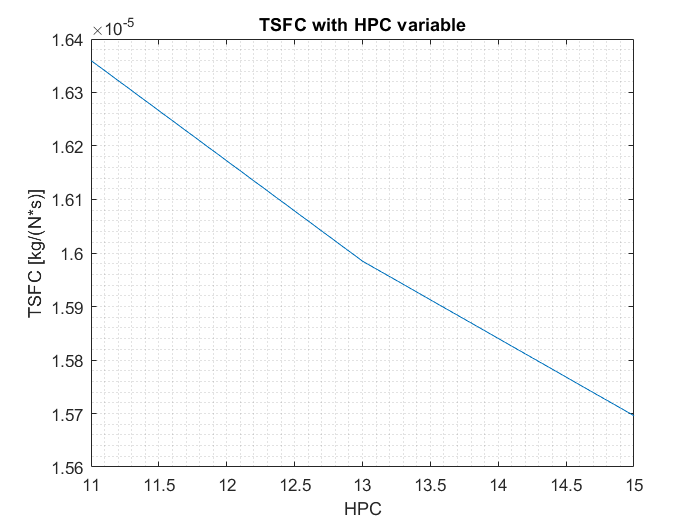

figure("Name","TSFC with HPC variable")
plot(VHPC,TSFC)
xlabel("HPC")
ylabel("TSFC [kg/(N*s)]")
title("TSFC with HPC variable")
grid("minor")


%once I have finished to upload the value of HPC, I put the
%original value for the next variations

pi_HPC = 12.5; %HPC Pressure Ratio

## Varying the turbine inlet temperature from [1400K, 1500,1600K]

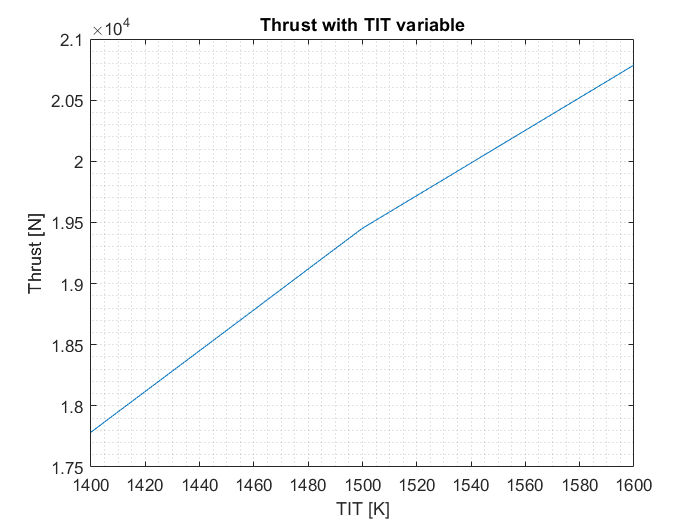

VTIT = [1400, 1500, 1600];

for i = 1:size(VTIT,2)
    TIT = VTIT(i);

    v_0 = M*sqrt(g_a*R*T_amb);
    T_ta = T_amb*(1+ ((g_a-1)/2)*M^2);
    T_t2 = T_ta;
    P_ta = P_amb*(1+ ((g_a-1)/2)*M^2)^(g_a/(g_a-1));
    P_t2 = P_ta*pi_inlet;
    %Fan
    P_t21 = P_t2*FPR;
    P_t13 = P_t21;
    T_t21 = T_t2*(1 + (1/eta_fan)*(FPR^((g_a-1)/g_a) -1));
    T_t13 = T_t21;
    W_fan = m*cp_a*(T_t21-T_t2);
    m_hot = m/(BPR+1);
    m_cold = m_hot*BPR;
    W_fan_hot = m_hot*cp_a*(T_t21-T_t2);
    W_fan_cold = m_cold*cp_a*(T_t21-T_t2);
    %Compressors
    P_t25 = P_t21*pi_LPC;
    P_t3 = P_t25*pi_HPC;
    T_t25 = T_t21*(1 + (1/eta_comp)*(pi_LPC^((g_a-1)/g_a) -1));
    T_t3 = T_t25*(1 + (1/eta_comp)*(pi_HPC^((g_a-1)/g_a) -1));
    W_LPC = m_hot*cp_a*(T_t25-T_t21);
    W_HPC = m_hot*cp_a*(T_t3-T_t25);
    %Combustion chamber
    m_f = (m_hot*(cp_gas*TIT-cp_a*T_t3))/(eta_comb*LHV);m_gas = m_hot + m_f;
    P_t4 = P_t3*pi_comb;
    %HPT:
    W_HPT = W_HPC/eta_mec;
    T_t45 = TIT-W_HPT/(m_gas*cp_gas);
    P_t45 = P_t4*(1- (1/eta_turb)*(1- T_t45/TIT))^(g_gas/(g_gas-1));
    %LPT:
    W_LPT = (W_LPC+W_fan)/eta_mec;
    W_45g = (W_LPC+W_fan_hot)/eta_mec;
    T_tg = T_t45- W_45g/(m_gas*cp_gas);
    T_t5 = T_t45- W_LPT/(m_gas*cp_gas);
    P_t5 = P_t45*(1- (1/eta_turb)*(1- T_t5/T_t45))^(g_gas/(g_gas-1));
    P_tg = P_t45*(1- (1/eta_turb)*(1- T_tg/T_t45))^(g_gas/(g_gas-1));
    P_8is = P_amb;
    T_8is = T_tg*(P_8is/P_tg)^((g_gas-1)/g_gas);
    W_gg = m_gas*cp_gas*(T_tg-T_8is);
    %Core Nozzle:
    T_t7 = T_t5;
    T_t8 = T_t7;
    P_t7 = P_t5;
    Crit_ratio = (1- (1/eta_noz)*((g_gas-1)/(g_gas+1)))^(-g_gas/(g_gas-1));
    if P_t7/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
        M_8 = 1;
        T_8 = T_t7*(2/(g_gas+1));
        P_8 = P_t7/(Crit_ratio);
        v_8 = sqrt(g_gas*R*T_8);
        r_8 = P_8/(R*T_8);
        A_8 = m_gas/(r_8*v_8);
    else %unchocked nozzle
        P_8 = P_amb;
        T_8 = T_t8*(1 -eta_noz*(1- (P_8/P_t7)^((g_gas-1)/g_gas)));
        M_8 = sqrt((T_t8/T_8 -1)*(2/(g_gas-1)));
        v_8 = M_8*sqrt(g_gas*R*T_8);
        r_8 = P_8/(R*T_8);
        A_8 = m_gas/(r_8*v_8);
    end
    P_t8 = P_8*(1 + ((g_gas-1)/2)*M_8^2)^(g_gas/(g_gas-1));
    %Bypass Nozzle:
    T_t16 = T_t13;
    P_t16 = P_t13;
    Crit_ratio = (1- (1/eta_noz)*((g_a-1)/(g_a+1)))^(-g_a/(g_a-1));
    if P_t16/P_amb >= Crit_ratio %Critical nozzle or chocked nozzle
        M_18 = 1;
        T_18 = T_t16*(2/(g_a+1));
        P_18 = P_t16/(Crit_ratio);
        v_18 = sqrt(g_a*R*T_18);
        r_18 = P_18/(R*T_18);
        A_18 = m_cold/(r_18*v_18);
    else %unchocked nozzle
        P_18 = P_amb;
        T_18 = T_t18*(1 -eta_noz*(1- (P_18/P_t16)^((g_a-1)/g_a)));
        M_18 = sqrt((T_t18/T_18 -1)*(2/(g_a-1)));
        v_18 = M_18*sqrt(g_a*R*T_18);
        r_18 = P_18/(R*T_18);
        A_18 = m_cold/(r_18*v_18);
    end
    P_t18 = P_18*(1 + ((g_a-1)/2)*M_18^2)^(g_a/(g_a-1));
    %Performance parameters:
    F_core = m_gas*v_8 - m_hot*v_0 + A_8*(P_8-P_amb);
    v_8eff = (m_hot*v_0+F_core)/m_gas;
    F_bp = m_cold*(v_18-v_0) + A_18*(P_18-P_amb);
    v_18eff = v_0+F_bp/m_cold;
    F(i) = F_core+F_bp;
    TSFC(i) = m_f/F(i);
end

figure("Name","Thrust with TIT variable")
plot(VTIT,F)
xlabel("TIT [K]")
ylabel("Thrust [N]")
title("Thrust with TIT variable")
grid("minor")

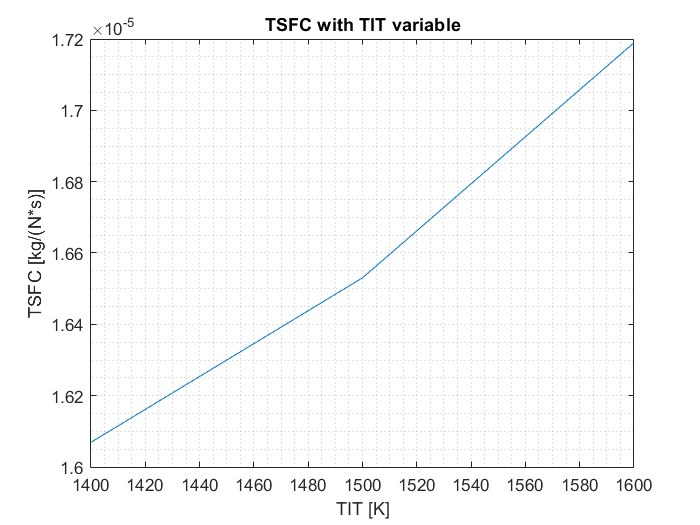

figure("Name","TSFC with TIT variable")
plot(VTIT,TSFC)
xlabel("TIT [K]")
ylabel("TSFC [kg/(N*s)]")
title("TSFC with TIT variable")
grid("minor")


%once I have finished to upload the value of TIT, I put the
%original value for the next variations

TIT = 1400; %Turbine Inlet Temperature [K]